clc
clear

root_dir = "C:\Users\olive\OneDrive - University of Surrey\individual project\data\raw_data";
testdate = "8mscatapultlogs";

file_num = 3;
path = root_dir + "/" + testdate + "/*.csv";
file_names = dir(path)

file_names = 18×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


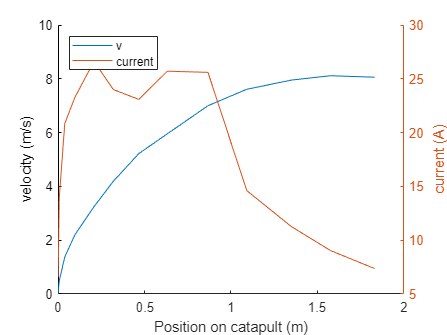

current_file = file_names(file_num);

file = importdata(strcat(current_file.folder, '\', current_file.name), ",");
catapult_data = file.data;
clf
hold on
plot(catapult_data(:,1), catapult_data(:,2))
ylabel("velocity (m/s)")
yyaxis right
ylabel("current (A)")
plot(catapult_data(:,1), abs(catapult_data(:,3)))
%scatter(data(:,1), data(:,4))
legend(["v", "current"], 'Location','northwest' )
hold off
xlabel("Position on catapult (m)")

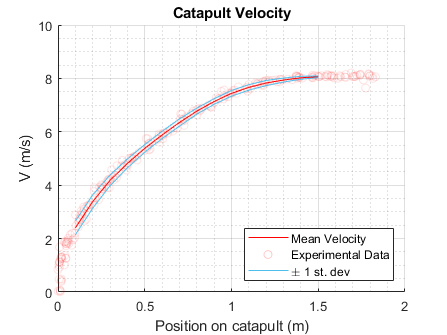

clf
hold on
catapult_new_distance = 0:0.1:2;
store_velocity = [];

for num = 1:18
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 1.84, :);
    new = interp1(catapult_data(2:end,1), catapult_data(2:end,2), catapult_new_distance);
    %scatter(catapult_new_time, new)
    scatter(catapult_data(:,1), catapult_data(:,2), "red", "HandleVisibility","off","MarkerEdgeAlpha",0.1)
    store_velocity(:,num) = new;
end


plot(catapult_new_distance, mean(store_velocity,2), "red", "DisplayName","Mean Velocity")

plot(catapult_new_distance, mean(store_velocity,2)+std(store_velocity,[],2), "Color",'#4DBEEE', "DisplayName","Mean Velocity","HandleVisibility","off")
plot(catapult_new_distance, mean(store_velocity,2)-std(store_velocity,[],2), "Color",'#4DBEEE', "DisplayName","Mean Velocity","HandleVisibility","off")
%dummy scatter for legend
scatter([-10],[-10],"red","MarkerEdgeAlpha",0.2,"DisplayName","Experimental Data");
plot([-10],[-10],"Color",'#4DBEEE',"DisplayName","\pm 1 st. dev");

leg = legend();
set(leg, 'Location', 'SouthEast')

hold off
ylabel("V (m/s)")
xlabel("Position on catapult (m)")
title("Catapult Velocity")
xlim([0,2])
grid
set(gca,'gridlinestyle','-')
grid minor

exportgraphics(gcf,'figures/catapult_velocity_position.png') 

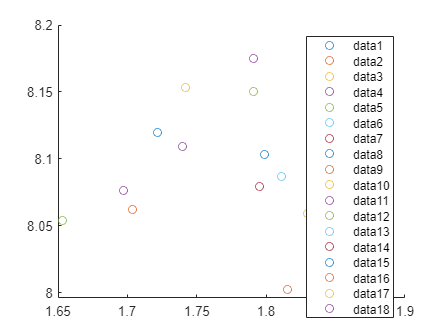

clf
hold on
for num = 1:18
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 2, :);
    scatter(catapult_data(end, 1), catapult_data(end, 2))
end
hold off
legend

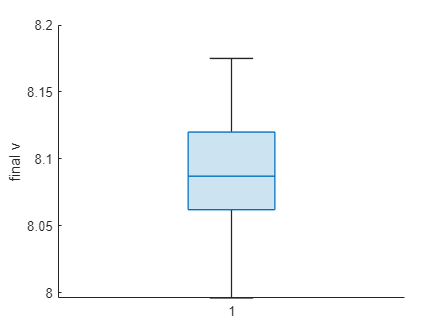

final_v = [];
clf
hold on
catapult_new_distance = 0:0.1:2;
for num = 1:18
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 2, :);
    final_v = [final_v catapult_data(end,2)];
end
boxchart(final_v);
hold off
ylabel("final v")

std(final_v)

ans = 0.0492

mean(final_v)

ans = 8.0926

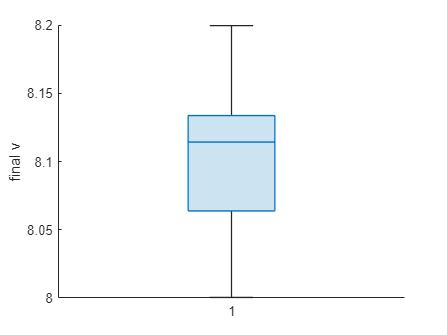

final_v_interp = [];
clf
hold on
catapult_new_distance = 0:0.1:2;
for num = 1:18
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 1.8, :);
    new = interp1(catapult_data(2:end,1), catapult_data(2:end,2), catapult_new_distance);
    final_v_interp = [final_v_interp new(18)];
end
boxchart(final_v_interp);
hold off
ylabel("final v")

std(final_v_interp,'omitnan')

ans = 0.0525

mean(final_v_interp,'omitnan')

ans = 8.1010

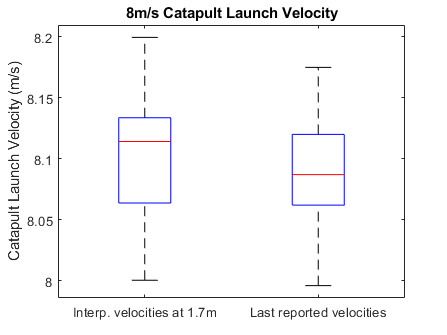

d = [final_v_interp', final_v'];
boxplot(d, 'labels',{'Interp. velocities at 1.7m','Last reported velocities'});
ylabel("Catapult Launch Velocity (m/s)")
title("8m/s Catapult Launch Velocity")
exportgraphics(gcf,'figures/catapult_launch_velocities.png') 